# **Problem 1.b**

Since I was unable to find any academic definition regarding a Minimum Mean Distance classifier, I will implement what I think could be called a Minimum Mean Distance classifier as follows:

- Calculate the mean of each class in the training dataset.

- Calculate the distance of the sample in question with some measure of distance (here we will Euclidean Distance) from each of the means.

- The sample belongs to the class from whose mean it is the least distant.

## **Analysis of the Iris Data:**

First we will read in the data set:

clearvars
num_classes = 3;
X_Iris = load("Data/Iris-Data_dat.txt");
input_size = size(X_Iris, 1)

input_size = 150

We will perform the leave-one-out method by seperating one sample from the entire dataset and going through steps 1-3 as described above.

I: Classification

preds = zeros([input_size, 1]);
X_Iris_labels = X_Iris(:, 1);
X_Iris_feats = X_Iris(:, 2:5);
mean_dists = zeros([input_size, num_classes]);
for i=1:input_size
    means = zeros([num_classes, 4]);
    % leave one out as test
    X_test_feats = X_Iris_feats(i,:);
    X_test_label = X_Iris_labels(i);
    % the rest will be used to infer the class of the left out sample
    X_train_feats = X_Iris_feats([1:i-1, i+1:end],:);
    X_train_labels = X_Iris_labels([1:i-1, i+1:end]);
    % calculate the mean of each class
    for j = 1:num_classes
        means(j, :) = mean(X_train_feats(X_train_labels == j, :), 1);
    end
    % euclidean distance from the test sample to each of the means and
    % assigning the minimum distance as the chosen class
    mean_dists(i,:) = sqrt(sum((repmat(X_test_feats, [num_classes, 1]) - means).^2, 2));
    [~, preds(i)] = min(mean_dists(i,:));
end


II. Evaluation

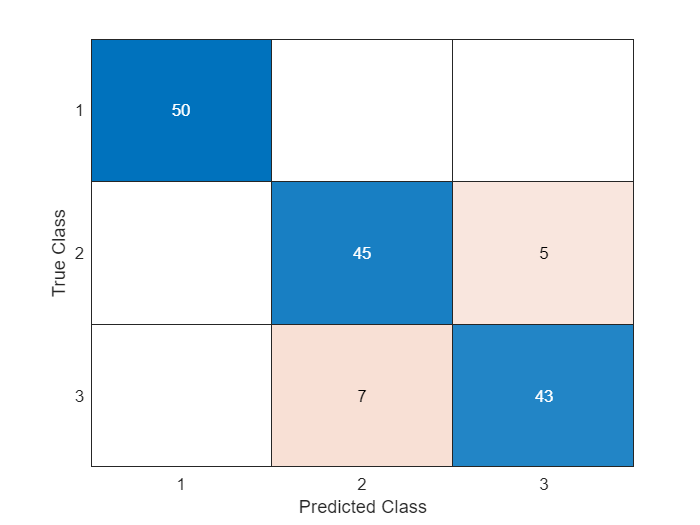

confusionchart(X_Iris_labels, preds);

accuracy = sum(preds == X_Iris_labels)/input_size

accuracy = 0.9200

Despite how simply and fast this classifier can perform, it seems that it can still achieve reasonably accurate results when compared $\mathrm{kNN}$ that has a major time complexity issue. We have to keep in mind however, that for both cases, $\mathrm{kNN}$ and $\mathrm{MMD}$ (as described here) the choice of the distance function is paramount. Our assumption here is that we're essentially dealing with multivariate samples drawn from Gaussians with $\Sigma =\sigma {\;}^2 I$ which is not necessarily true but it is usually a good enough estimate.

We can also print out the distance values of the misclassified samples:

disp('Distances from Mean of the first, the second and the third class respectively of the misclassified samples:');

Distances from Mean of the first, the second and the third class respectively of the misclassified samples:


mean_dists(preds ~= X_Iris_labels, :)

ans =    39.8050   12.5642   11.5698
   41.3366   12.4057    9.0277
   40.1083   10.4285   10.1617
   42.0528   11.7417    6.5131
   40.7264    9.0677    8.9811
   34.9514   11.5917   21.1276
   41.1543   10.6324   11.7174
   40.7259    9.5230   12.6061
   39.5520    9.8877   12.2117
   39.2137    7.6608    9.1120


We can see that most of the misclassified samples are almost equidistant from the two closest means, leading to a misclassification. This implies that were likely on or close to the respective Bayesian decision boundary.

## **Analysis of the Liquid Data:**

Steps are similar to the previous section so we will avoid detailed explanation in favor of brevity.

clearvars
num_classes = 3;
X_Liquid = load("Data/Liquid-Data_dat.txt");
input_size = size(X_Liquid, 1)

input_size = 178

I: Classification

preds = zeros([input_size, 1]);
X_Liquid_labels = X_Liquid(:, 1);
X_Liquid_feats = X_Liquid(:, 2:7);
mean_dists = zeros([input_size, num_classes]);
for i=1:input_size
    means = zeros([num_classes, 6]);
    X_test_feats = X_Liquid_feats(i,:);
    X_test_label = X_Liquid_labels(i);
    X_train_feats = X_Liquid_feats([1:i-1, i+1:end],:);
    X_train_labels = X_Liquid_labels([1:i-1, i+1:end]);
    for j = 1:num_classes
        means(j, :) = mean(X_train_feats(X_train_labels == j, :), 1);
    end
    mean_dists(i,:) = sqrt(sum((repmat(X_test_feats, [num_classes, 1]) - means).^2, 2));
    [~, preds(i)] = min(mean_dists(i,:));
end


II. Evaluation

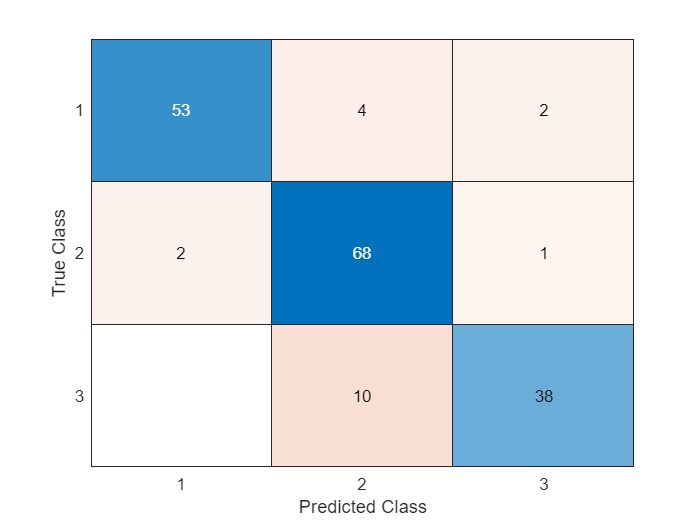

cc = confusionchart(X_Liquid_labels, preds);

accuracy = sum(preds == X_Liquid_labels)/input_size

accuracy = 0.8933

disp('Distances from Mean of the first, the second and the third class respectively of the misclassified samples:');

Distances from Mean of the first, the second and the third class respectively of the misclassified samples:


mean_dists(preds ~= X_Liquid_labels, :)

ans =   412.7873  280.2001  381.2223
  381.1510  299.4945  363.5841
  368.4894  343.4285  479.5434
  368.1554  382.4119  364.0283
  334.4569  446.8900  329.7688
  464.0935  234.1111  359.6510
  694.6630  290.6884  262.0636
  266.7225  487.3734  582.0209
  373.8468  427.3496  595.0008
  543.3706  183.5608  341.6436


Similar to the first example most of the misclassifications occur when the sample is nearly equidistant from the closest two means.

## **Analysis of the Normal Data:**

We will use the means of the training data to try and classify the samples from the test data, working under the assumption that the training data provides a general enough dataset so that its means are close to the mean of the entire dataset for each class.

clearvars
X_Normal_test = load("Data/Normal-Data-Testing_dat.txt");
X_Normal_train = load("Data/Normal-Data-Training_dat.txt");
num_classes = 2;
input_size = size(X_Normal_test, 1)

input_size = 1000

X_Normal_test_feats = X_Normal_test(:, 2:3);
X_Normal_test_labels = X_Normal_test(:, 1);
X_Normal_train_feats = X_Normal_train(:, 2:3);
X_Normal_train_labels = X_Normal_train(:, 1);
means_train = zeros([num_classes, 2]);
% calculate the mean of each class from the train data
for i = 1:num_classes
    means_train(i, :) = mean(X_Normal_train_feats(X_Normal_train_labels == i, :), 1);
end
means_train

means_train =    -0.0063    0.1166
    3.9954   -0.0185


I. Classification

preds = zeros([input_size, 1]);
mean_dists = zeros([input_size, num_classes]);
for i = 1:input_size
    mean_dists(i,:) = sqrt(sum((repmat(X_Normal_test_feats(i,:), [num_classes, 1]) - means_train).^2, 2));
    [~, preds(i)] = min(mean_dists(i,:));
end

II. Evaluation

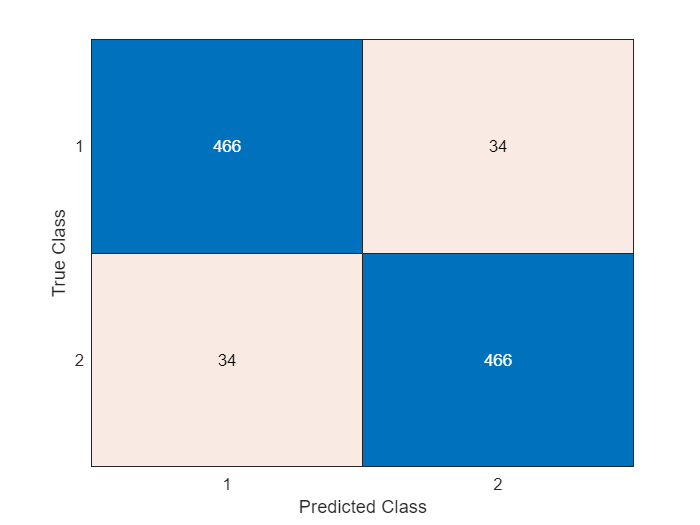

confusionchart(X_Normal_test_labels, preds);

accuracy = sum(preds == X_Normal_test_labels)/input_size

accuracy = 0.9320

disp('Distances from Mean of the first, the second and the third class respectively of the misclassified samples:');

Distances from Mean of the first, the second and the third class respectively of the misclassified samples:


mean_dists(preds ~= X_Normal_test_labels, :)

ans =     2.0232    2.0150
    5.2080    2.2051
    2.6434    2.5888
    3.8029    0.7311
    3.4444    1.6896
    3.1128    1.0526
    2.3115    1.8276
    2.6763    1.3277
    3.2942    2.5828
    2.8993    2.6373


And if we were to filter these by smaller than 0.5 difference between the distances from each of the means:

mean_dists(preds ~= X_Normal_test_labels & mean_dists(:, 1) - mean_dists(:, 2) < 0.5, :)

ans =     2.0232    2.0150
    2.6434    2.5888
    2.3115    1.8276
    2.8993    2.6373
    2.5479    2.4022
    4.3083    3.9579
    2.1481    1.9044
    2.2434    2.1124
    2.2204    1.9169
    2.0199    2.0060


Which constitutes $64%$ of the misclassifications. Confirming that a majority of these misclassified samples are almost the same distant from both means.